# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

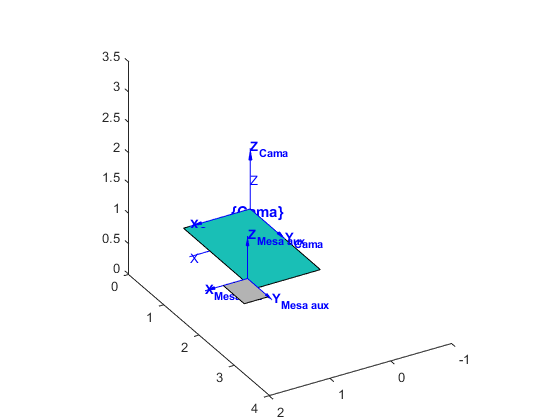

clc;
clear;
close all;

A= 1.1;
L_cama = 2;

aux_A= 0.4;
aux_L = 0.6;

centro_cama = [0 0 0.5];
centro_aux = [1.2 2 0.7];

%escalado = 0.075; % escala del cranio y tumor para que este acorde al tamaño del humano

yaw = 0; %eje z
roll = 0; % eje x
pitch = 0; % eje y

yaw_aux = 0; %eje z
roll_aux = 0; % eje x
pitch_aux = 0; % eje y

mat_aux = [ 0 0 0 1; aux_A 0 0 1; aux_A aux_L 0 1; 0 aux_L 0 1]';
mat_cama = [ 0 0 0 1; A 0 0 1; A L_cama 0 1; 0 L_cama 0 1]';

r = rpy2r(roll, pitch, yaw,'deg');
r = r2t(r);

r_aux = rpy2r(roll_aux, pitch_aux, yaw_aux,'deg');
r_aux = r2t(r_aux);

FA = transl(centro_cama)*r; %cama 
FB = transl(centro_aux)*r_aux; %mesa aux

mat_cama = transl(centro_cama)*r*mat_cama;
mat_cama = mat_cama(1:3,:);

mat_aux = transl(centro_aux)*r_aux*mat_aux;
mat_aux = mat_aux(1:3,:);

hold on
s= fill3(mat_cama(1,:), mat_cama(2,:), mat_cama(3,:), [1 1 1 1]);
set(s,'facealpha',1);

s2= fill3(mat_aux(1,:), mat_aux(2,:), mat_aux(3,:), [0.7 0.7 0.7]);
set(s2,'facealpha',1);

trplot(eye(4)); % mundo
trplot(FA, ... 
    'frame', 'Cama', ...
    'color', 'b',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
     'length',1,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);
trplot(FB, ... 
    'frame', 'Mesa aux', ...
    'color', 'b',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
     'length',0.7,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1);

axis([-1 2 0 4 0 3.5])

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

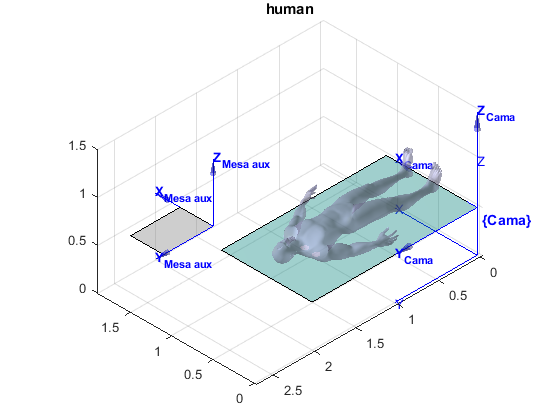

altura_human = 1.80;

load('SP_material/F_V_Human_Body.mat');
% Para redimensionar al cuerpo multiplicamos los vertices
max_y = max(V(:,2));

tamano = altura_human/max_y;

V = V*tamano;
% Buscamos la anchura después de hacer el escalado.
min_z_humano = min(V(:,3));

%centramos al humano en la mesa
centrado = altura_human/2;

V(:,4) = ones(size(V,1),1); % Añadir fila de 1 para poder trasladar
V = V'; % Transponer para hacer la multiplicacion
V = transl(A/2,-centrado+L_cama/2,-min_z_humano)*V;
V = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*V;
V = V(1:3,:);
V = V';


stlPlot(V,F,'human')
alpha 0.4;
axis equal;

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

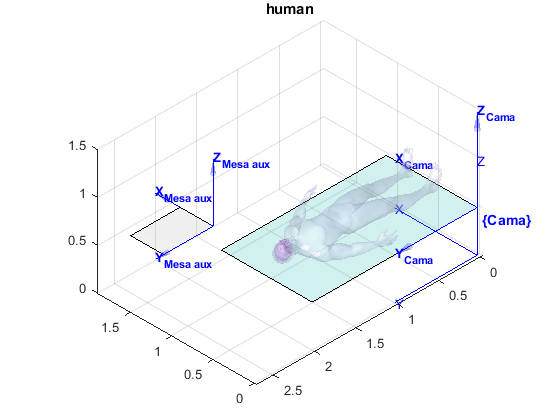

load('Crani_red.mat');

% el ancho max del craneo, desde los ojos a la parte de atras es de 199.2251mm
% Para redimencionar
fv.vertices = fv.vertices/1000; % Pasamos el craneo de mm a metros
%fv.vertices = fv.vertices*escalado; % Buscamos un factor de multiplicacion que escale el craneo dentro de la cabeza

max_min_crani(1,1) = max(fv.vertices(:,1)); %max x
max_min_crani(2,1) = min(fv.vertices(:,1)); % min x

max_min_crani(1,2) = max(fv.vertices(:,2)); % max y
max_min_crani(2,2) = min(fv.vertices(:,2)); % min y

max_min_crani(1,3) = max(fv.vertices(:,3)); % max z
max_min_crani(2,3) = min(fv.vertices(:,3)); % min z

centro_crani_origen = [(max_min_crani(1,1)+max_min_crani(2,1))/2,(max_min_crani(1,2)+max_min_crani(2,2))/2,(max_min_crani(1,3)+max_min_crani(2,3))/2];


% para luego centrar la parte de arriba del craneo con la parte de arriba de la cabeza del
% humano, buscamos el z max de la posición inicial

fv.vertices(:,4) = ones(size(fv.vertices,1),1); % Añadir fila de 1 para poder trasladar
fv.vertices = fv.vertices'; % Transponer para hacer la multiplicacion
  
centro_crani(:,4) = ones(size(centro_crani_origen,1),1); % Añadir fila de 1 para poder trasladar
centro_crani = centro_crani'; % Transponer para hacer la multiplicacion

MTC = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r...
    *transl(0,centrado-max_min_crani(1,3),0)...
    *transl(A/2,L_cama/2,-min_z_humano)*trotx(-90, 'deg'); %rotamos y centramos a la mesa, subimos para que este a la altura de la cabeza, trasladamos a la posicion de la mesa

fv.vertices = MTC*fv.vertices;
centro_crani = MTC*centro_crani;

fv.vertices = fv.vertices(1:3,:);
fv.vertices = fv.vertices';

centro_crani = centro_crani(1:3,:);
centro_crani = centro_crani';

patch(fv,'FaceColor',       [0.7 0.5 0.9], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);
     
camlight('headlight');
material('shiny');

alpha 0.2;


% axis('image');
%view([-135 35]);


4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

x_tumor = [0.139704486 0.145384743 0.134098829 0.139022429 0.140759543 0.145970886 0.132436314 0.144233771 0.137573057 0.140759543 0.1303262 0.137914086 0.148571229 0.130912343 0.131775571 0.146258629 0.136986914 0.138724029 0.139885657 0.141047286 0.150894486 0.129175229 0.139885657 0.144233771 0.139022429 0.148283486 0.153207086 0.129175229 0.138724029 0.144233771 0.138436286 0.147995743 0.153494829 0.129175229 0.137573057 0.144233771 0.153793229 0.1280136 0.141622771 0.143359886 0.1549442 0.1280136 0.141047286 0.141910514 0.155231943 0.126276486 0.1427844 0.143946029 0.1280136 0.121352886 0.156393571 0.128589086 0.143072143 0.1427844 0.126276486 0.155231943 0.119903514 0.1280136 0.152919343 0.143647629 0.134674314 0.149157371 0.125690343 0.119328029 0.1575552 0.127139714 0.1500206 0.139022429 0.148869629 0.1333102 0.127725857 0.119328029 0.1575552 0.126851971 0.142496657 0.133800429 0.151469971 0.126276486 0.121065143 0.158130686 0.126564229 0.142496657 0.134674314 0.149445114 0.126564229 0.158418429 0.122216114 0.125988743 0.131487829 0.147708 0.137285314 0.133224943 0.149445114 0.158716829 0.124539371 0.152056114 0.131487829 0.141622771 0.149157371 0.1329372 0.1549442 0.125690343 0.156105829 0.126276486 0.148571229 0.134098829 0.146546371 0.134386571 0.154368714 0.125114857 0.156681314 0.1280136 0.147420257 0.133512686 0.137573057 0.153793229 0.125988743 0.155231943 0.134098829 0.138148543 0.1500206 0.127139714 0.156393571 0.129462971 0.145970886 0.137285314 0.1427844 0.130613943 0.156105829 0.127438114 0.145683143 0.138724029 0.133800429 0.147132514 0.154368714 0.128589086 0.144809257 0.136699171 0.139597914 0.152343857 0.128876829 0.146258629 0.140407857 0.139885657 0.147420257 0.131487829 0.139022429 0.135835943 0.145097 0.132063314 0.138724029]';
y_tumor = [0.109907114 0.104557229 0.103683343 0.097310371 0.112955057 0.108894686 0.101658486 0.101083 0.096447143 0.113818286 0.109768571 0.108031457 0.105420457 0.104844971 0.101456 0.100209114 0.094997771 0.094710029 0.094411629 0.116141543 0.104557229 0.104557229 0.094123886 0.121640629 0.117292514 0.115843143 0.1057082 0.104258829 0.092972914 0.122216114 0.118454143 0.117004771 0.105239286 0.104557229 0.090649657 0.121352886 0.1057082 0.1033956 0.088337057 0.121640629 0.105420457 0.104557229 0.087175429 0.121065143 0.1033956 0.102233971 0.086599943 0.122514514 0.111793429 0.104258829 0.103107857 0.097598114 0.0860138 0.122802257 0.111217943 0.110344057 0.102521714 0.097896514 0.094710029 0.085150571 0.120766743 0.1181664 0.1106318 0.1057082 0.103107857 0.097022629 0.087175429 0.0860138 0.121352886 0.120106 0.111793429 0.106294343 0.101946229 0.097907171 0.085438314 0.121640629 0.117004771 0.109768571 0.105995943 0.103971086 0.098472 0.085726057 0.122514514 0.121065143 0.109182429 0.104557229 0.103683343 0.099335229 0.088049314 0.087175429 0.0863122 0.121640629 0.121065143 0.105995943 0.104557229 0.094411629 0.088049314 0.0863122 0.121065143 0.119903514 0.112667314 0.108894686 0.098184257 0.094123886 0.089200286 0.086887686 0.120479 0.120479 0.112667314 0.106869829 0.099335229 0.092972914 0.088912543 0.087750914 0.120479 0.112368914 0.106582086 0.097598114 0.087750914 0.119615771 0.114404429 0.104844971 0.103107857 0.092674514 0.091523543 0.087463171 0.1181664 0.1106318 0.104258829 0.096734886 0.092386771 0.088049314 0.114404429 0.113029657 0.101658486 0.098759743 0.0935484 0.088049314 0.114692171 0.102521714 0.101083 0.096734886 0.088571514 0.110344057 0.102233971 0.100209114 0.090361914 0.1083192 0.1007846 0.098184257 0.091523543]';
z_tumor = [0.0336 0.0336 0.0336 0.0336 0.035 0.035 0.035 0.035 0.035 0.0364 0.0364 0.0364 0.0364 0.0364 0.0364 0.0364 0.0364 0.0364 0.0364 0.0378 0.0378 0.0378 0.0378 0.0392 0.0392 0.0392 0.0392 0.0392 0.0392 0.0406 0.0406 0.0406 0.0406 0.0406 0.0406 0.042 0.042 0.042 0.042 0.0434 0.0434 0.0434 0.0434 0.0448 0.0448 0.0448 0.0448 0.0462 0.0462 0.0462 0.0462 0.0462 0.0462 0.0476 0.0476 0.0476 0.0476 0.0476 0.0476 0.0476 0.049 0.049 0.049 0.049 0.049 0.049 0.049 0.049 0.0504 0.0504 0.0504 0.0504 0.0504 0.0504 0.0504 0.0518 0.0518 0.0518 0.0518 0.0518 0.0518 0.0518 0.0532 0.0532 0.0532 0.0532 0.0532 0.0532 0.0532 0.0532 0.0532 0.0546 0.0546 0.0546 0.0546 0.0546 0.0546 0.0546 0.056 0.056 0.056 0.056 0.056 0.056 0.056 0.056 0.0574 0.0574 0.0574 0.0574 0.0574 0.0574 0.0574 0.0574 0.0588 0.0588 0.0588 0.0588 0.0588 0.0602 0.0602 0.0602 0.0602 0.0602 0.0602 0.0602 0.0616 0.0616 0.0616 0.0616 0.0616 0.0616 0.063 0.063 0.063 0.063 0.063 0.063 0.0644 0.0644 0.0644 0.0644 0.0644 0.0658 0.0658 0.0658 0.0658 0.0672 0.0672 0.0672 0.0672]';
tumor = [x_tumor,y_tumor,z_tumor];
clear x_tumor;
clear y_tumor;
clear z_tumor;


*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

%% put your code Here

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

% el codigo ya esta en la siguiente seccion por ahora
% mdl_puma560;
% p560.base = SE3(centro_cama(1)+0.5,centro_cama(2)+0.5+L_cama, centro_cama(3)+0.75);
% p560.tool = SE3(0, 0, -0.15);
% %p560.plot(qz,'nowrist','floorlevel',0,'scale',0.5,'perspective','notiles');
% p560.plot(qz,'floorlevel',0,'scale',0.5,'perspective','notiles');
%axis([0 3 0 3 -1 3])

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

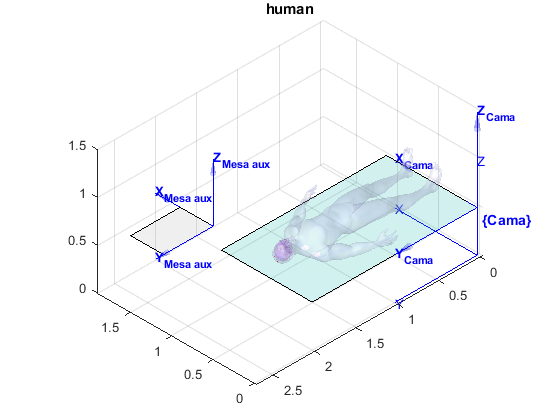

% añadimos los fiducials en el mismo sistema de coordenadas del tumor
fiducials = [0.1303 0.2218 0.02166 ;0.05472 0.2230 0.05472; 0.0745 0.2270 0.09234];  		
top_diacom = [0.1334061 0.1588767 0.0014000];

tumor(:,4) = ones(size(tumor,1),1); % Añadir fila de 1 para poder trasladar
tumor = tumor'; % Transponer para hacer la multiplicacion

fiducials(:,4) = ones(size(fiducials,1),1);
fiducials = fiducials'; 

top_diacom(:,4) = ones(size(top_diacom,1),1);
top_diacom = top_diacom'; 

top_craneo = [centro_crani_origen(1)-0.01, centro_crani_origen(2)+0.02, max_min_crani(1,3)];

MT = MTC...
    *troty(-180,'deg')...
    *transl(-top_diacom(1,1),-top_diacom(2,1),-top_diacom(3,1))...
    *transl(-top_craneo(1),-top_craneo(2),-top_craneo(3)); % centramos al eje de coordenadas

fiducials = MT*fiducials;
tumor= MT*tumor;
top_diacom = MT*top_diacom;

fiducials = fiducials(1:3,:);
fiducials = fiducials';
 
top_diacom = top_diacom(1:3,:);
top_diacom = top_diacom';

tumor = tumor(1:3,:);
tumor = tumor';

plot_sphere(fiducials(1,:),0.004,'r');
plot_sphere(fiducials(2,:),0.004,'r');
plot_sphere(fiducials(3,:),0.004,'r');

% plot_sphere(top_diacom,0.004,'g');

max_min_tumor(1,1) = max(tumor(:,1)); % max x
max_min_tumor(2,1) = min(tumor(:,1)); % min x

max_min_tumor(1,2) = max(tumor(:,2)); % max y
max_min_tumor(2,2) = min(tumor(:,2)); % min y

max_min_tumor(1,3) = max(tumor(:,3)); % max z
max_min_tumor(2,3) = min(tumor(:,3)); % min z

centro_tumor = [(max_min_tumor(1,1)+max_min_tumor(2,1))/2,(max_min_tumor(1,2)+max_min_tumor(2,2))/2,(max_min_tumor(1,3)+max_min_tumor(2,3))/2];


8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

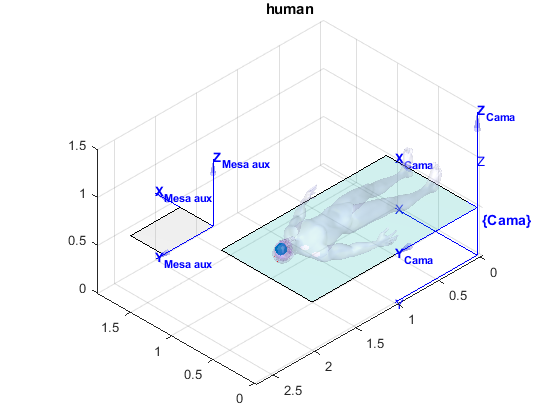

% el tumor hay que girarlo primero 180grados en Y y 90 en x. Para que este bien
%tumor = transl(A/2,L/2,-max_min_tumor(2,3))*trotx(90,'deg')*troty(-180,'deg')*tumor; %rotamos y centramos a la mesa
% tumor = trotx(90,'deg')*troty(-180,'deg')*tumor; %rotamos y centramos a la mesa
% %tumor = transl(0,centrado-max_min_tumor(1,3),-min_z_humano)*tumor; % subimos para que este a la altura de la cabeza
% tumor = transl(centro_crani(1),centro_crani(2),centro_crani(3))*tumor; % subimos para que este a la altura de la cabeza
% x = tumor(1,:);
% y = tumor(2,:);
% z = tumor(3,:);

x = tumor(:,1);
y = tumor(:,2);
z = tumor(:,3);
scatter3(x,y,z,'filled');

%plot3(tumor(1,:),tumor(2,:),tumor(3,:));
%axis([-1 2 -1 2 -1 2])    

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

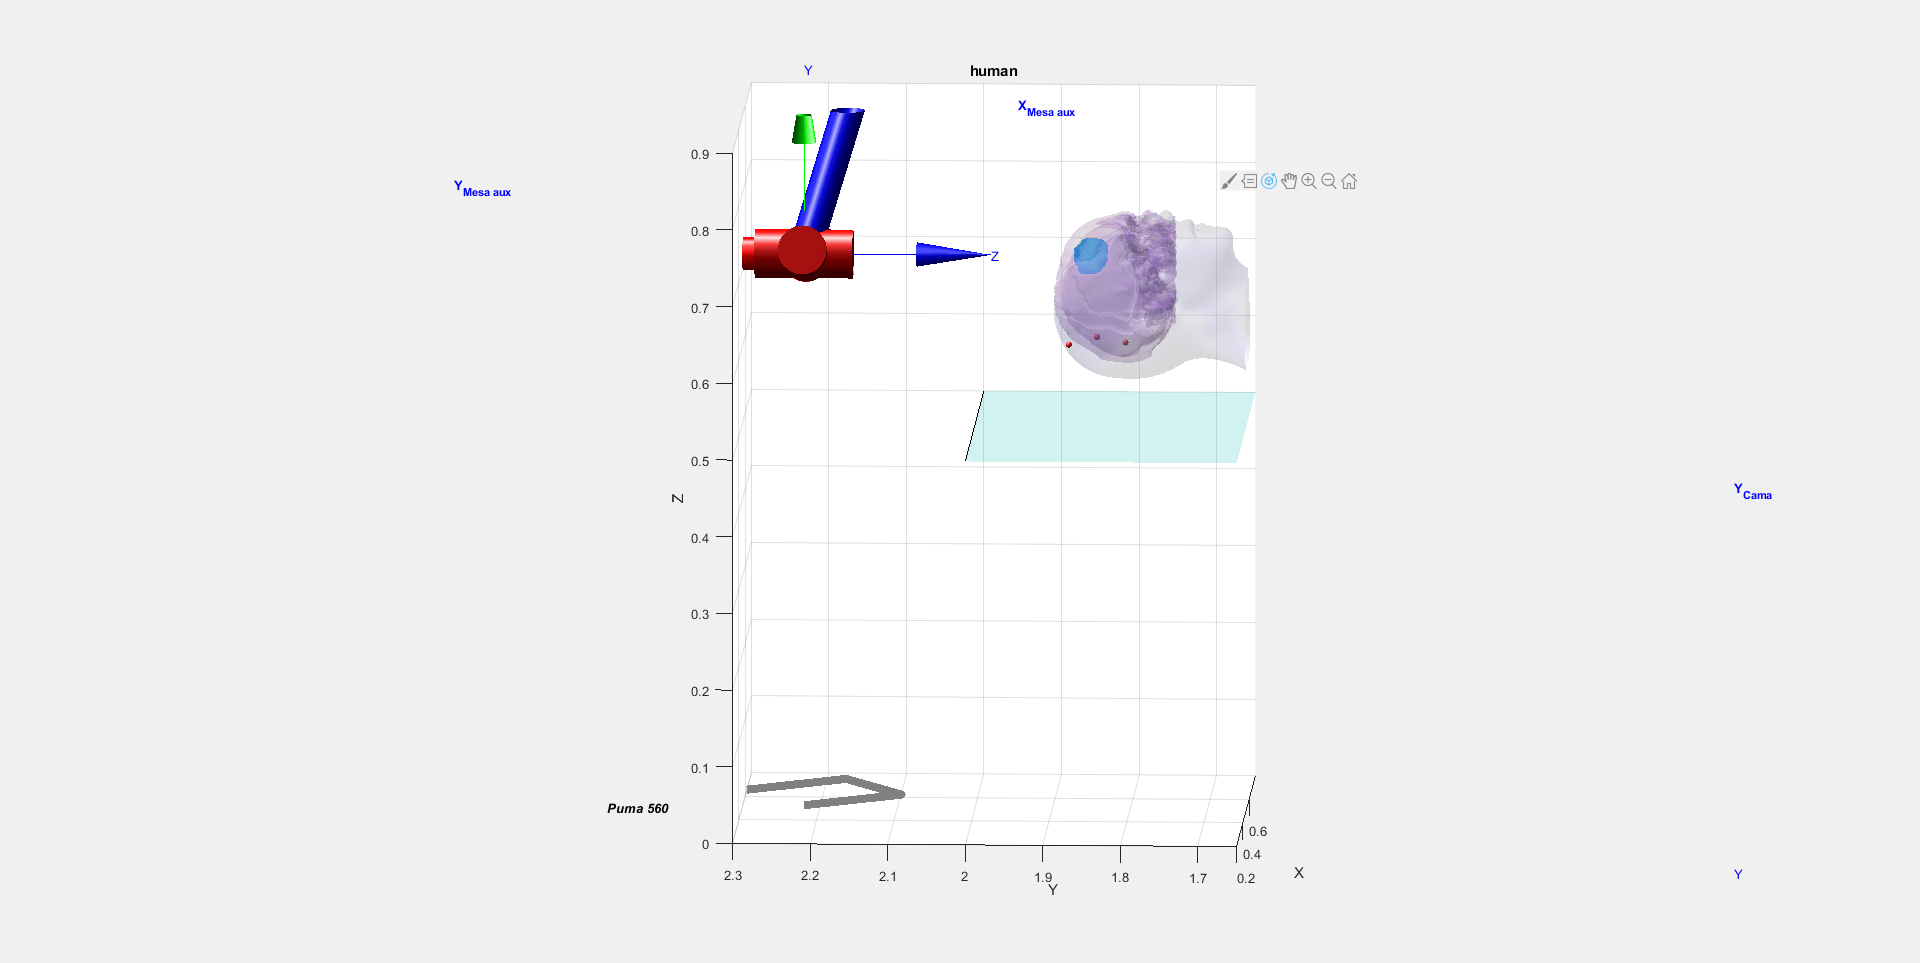

mdl_puma560;
p560.base = SE3(centro_cama(1)+0.5,centro_cama(2)+0.5+L_cama, centro_cama(3)+0.75);
p560.tool = SE3(0, 0, 0.17);

%p560.plot(qz,'nowrist','floorlevel',0,'scale',0.5,'perspective','notiles');
p560.plot(qz,'floorlevel',0,'scale',0.5,'perspective','notiles');
axis([0 2 0 3 0 2])

%Colocar el robot en la parte superior del cráneo
T = transl(centro_tumor(1),centro_tumor(2)+0.2,centro_tumor(3))*trotx(pi/2);% * troty(pi) * trotx(pi/2);
%+qr(1) = pi/4;
qqr = p560.ikine6s(T,'r');
qrt = jtraj(qz, qqr, 50);
scatter3(centro_tumor(1),centro_tumor(2)+0.2,centro_tumor(3),'filled');
p560.plot(qrt);



%Zoom en plan cutre
axis([0.2 0.8 1.65 2.3 0 0.9])    

%Entrar en el cerebro siguiendo una trayectoria recta
T2 = transl(centro_tumor(1),centro_tumor(2),centro_tumor(3))*trotx(pi/2);

qrt = ctraj(T, T2, 50);
qqr2 = p560.ikine6s(qrt,'r');
p560.plot(qqr2);

%Salir del cerebro siguiendo la misma trayectoria
qrt = ctraj(T2, T, 50);
qqr3 = p560.ikine6s(qrt,'r');
p560.plot(qqr3);

10.- Prepare a script that perform trepanation.

*Add your comemnts her**e.....be concise*

%Posicion para cortar en el cerebro siguiendo una trayectoria recta

T3 = T*transl(0,0,centro_crani(3)-0.55);
scatter3(T2(1,4),T2(2,4),T2(3,4),'filled');
qrt = ctraj(T, T3, 50);
qqr2 = p560.ikine6s(qrt,'r');
p560.plot(qqr2);



radius = (max_min_tumor(1,3)-max_min_tumor(2,3))/2; % max en z - min en z, ancho tumor
n=100;
%INI = qrt; %center of the part
INI = transl(A/2+centro_cama(1), max_min_crani(1,2), -min_z_humano+centro_cama(3));


scatter3(INI(1,4),INI(2,4),INI(3,4),'filled');

% center is an array [x,y,z]
% normal is an array [nx,ny,nz]
% radius is a value
% E.g., plotCircle3D([0,0,0],[-1,0,0],1) 


plotCircle3D([A/2+centro_cama(1), max_min_crani(1,2), -min_z_humano+centro_cama(3)],[centro_cama(1) -1 -min_z_humano],radius);

for i=1:n
%Laser_Pose(:,:,i)= INI*trotx(-pi/4)*troty(2*pi*i/n)*transl(0, 0, radius);
Laser_Pose(:,:,i)= INI*troty(2*pi*i/n)*transl(radius,0,0)*trotx(pi/2)*troty(-pi/4);
end


Q= p560.ikine6s(Laser_Pose, 'run'); 

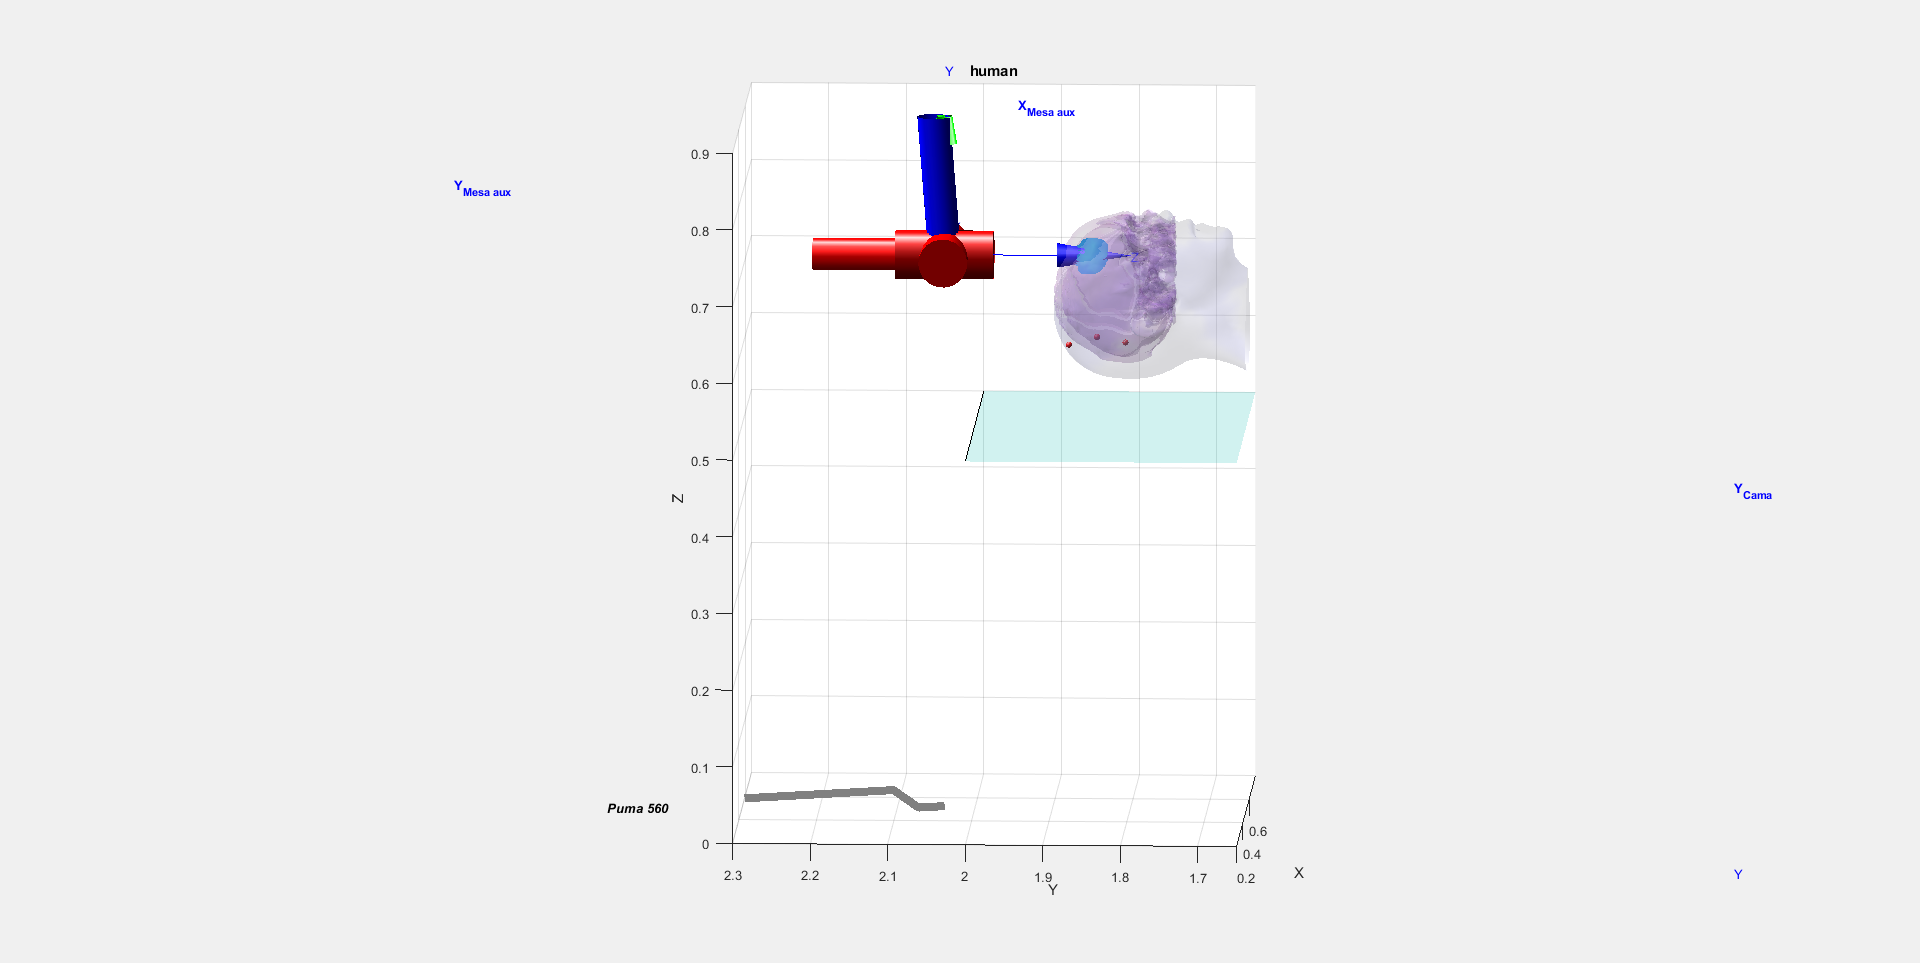

Error using matlab.graphics.primitive.Transform/set
Invalid value for Matrix property

Error in SerialLink/animate (line 107)
                            set(h.link(L), 'Matrix', T.T);

Error in SerialLink/plot (<a h


p560.plot(Q)

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*


%Colocar el robot en la parte superior del cráneo
T = transl(centro_crani(1),centro_crani(2)+0.6,centro_crani(3)) * troty(pi) * trotx(pi/2);
qr(1) = pi/4;
qqr = p560.ikine6s(T,'r');
qrt = jtraj(qr, qqr, 50);
p560.plot(qrt);

n=10;

for i=1:n
    %Entrar en el cerebro siguiendo una trayectoria
    T2 = T*trotx(-pi/4)*troty(2*pi*i/n)*transl(0,0,centro_crani(3)-0.3);
    qrt = ctraj(T, T2, 50);
    qqr2 = p560.ikine6s(qrt,'r');
    p560.plot(qqr2);
    
    %Salir del cerebro siguiendo la misma trayectoria
    qrt = ctraj(T2, T, 50);
    qqr3 = p560.ikine6s(qrt,'r');
    p560.plot(qqr3);
end


*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts her**e.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts her**e.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

## put your code Here